% Cargar el archivo de audio
file_path = 'C:\Users\Luis Gabriel\Downloads\cuarta.wav'

file_path = 'C:\Users\Luis Gabriel\Downloads\cuarta.wav'

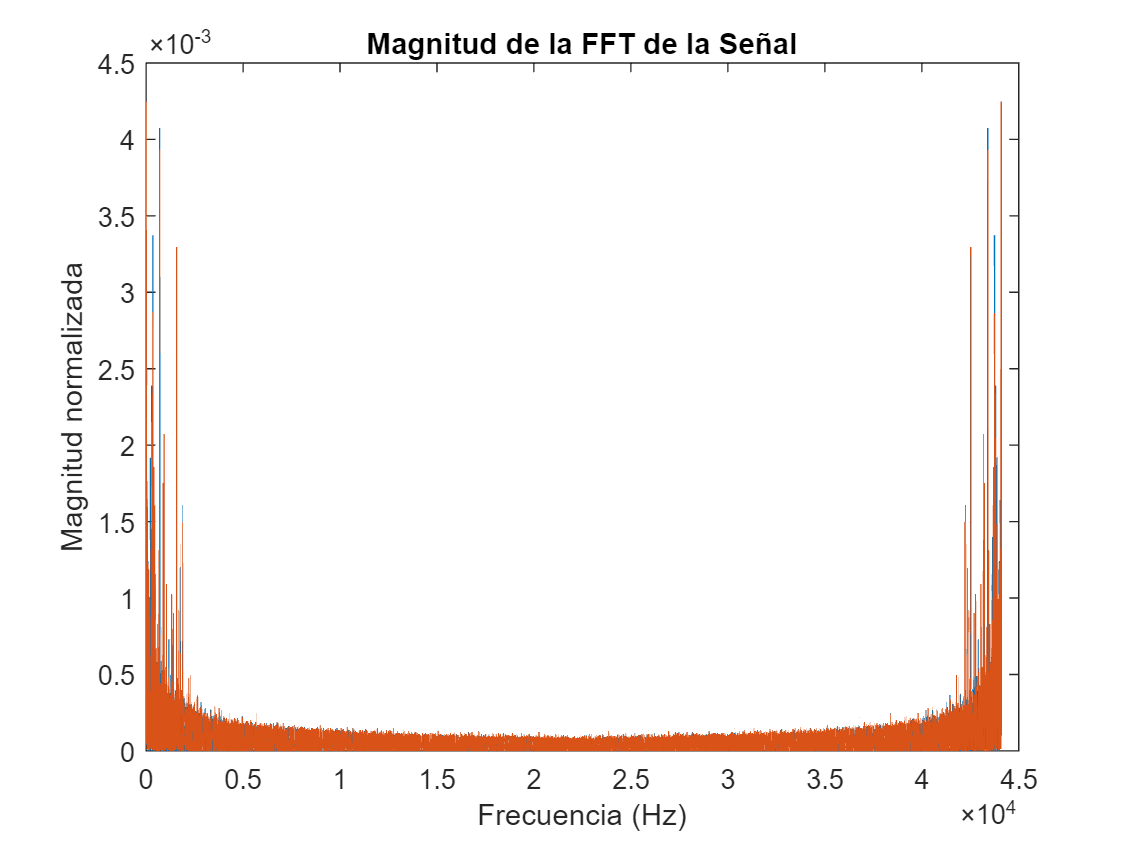

[y, fs] = audioread(file_path);

% Obtener información sobre la señal
Ts = 1 / fs;                 % Periodo de muestreo en segundos
N = length(y);               % Número de muestras
duration = N * Ts * 1000;    % Duración de la señal en milisegundos

% Calcular la FFT y obtener información de frecuencia
Y = fft(y);
frequencies = linspace(0, fs, N);  % Eje de frecuencia en Hz
magnitude = abs(Y) / N;            % Magnitud normalizada

% Graficar la magnitud de la FFT
figure;
plot(frequencies, magnitude);
title('Magnitud de la FFT de la Señal');
xlabel('Frecuencia (Hz)');
ylabel('Magnitud normalizada');

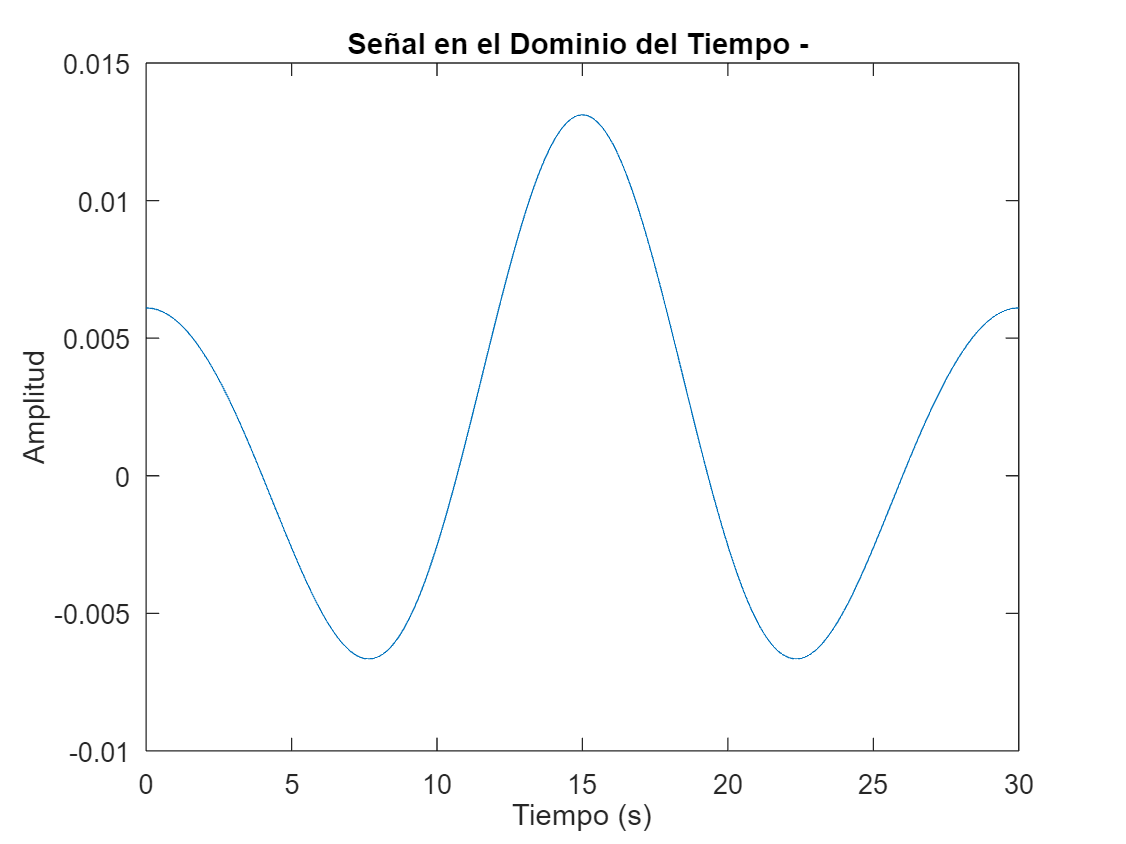


% Obtener valores de amplitud y frecuencia
A0 = abs(Y(1)) / N;
A1 = 2 * abs(Y(2)) / N;
A2 = 2 * abs(Y(3)) / N;
A3 = 2 * abs(Y(4)) / N;
f1 = frequencies(2);
f2 = frequencies(3);
f3 = frequencies(4);

% Crear la ecuación de la señal
t = 0:Ts:(N-1)*Ts;
signal = A0 - A1 * cos(2*pi*f1*t) + A2 * cos(2*pi*f2*t) - A3 * cos(2*pi*f3*t);

% Graficar la señal en el dominio del tiempo
figure;
plot(t, signal);
title('Señal en el Dominio del Tiempo - ');
xlabel('Tiempo (s)');
ylabel('Amplitud');


% Mostrar información al usuario
fprintf('Frecuencia de muestreo (fs): %d Hz\n', fs);

Frecuencia de muestreo (fs): 44100 Hz


fprintf('Periodo de muestreo (Ts): %.6f s\n', Ts);

Periodo de muestreo (Ts): 0.000023 s


fprintf('Número de muestras (N): %d\n', N);

Número de muestras (N): 1323000


fprintf('Duración de la señal: %.2f ms\n', duration);

Duración de la señal: 30000.00 ms


fprintf('Resolución en frecuencia de la FFT: %.2f Hz\n', fs/N);

Resolución en frecuencia de la FFT: 0.03 Hz
